# 3D Pan-Tilt Sensor Results

## Error Plot

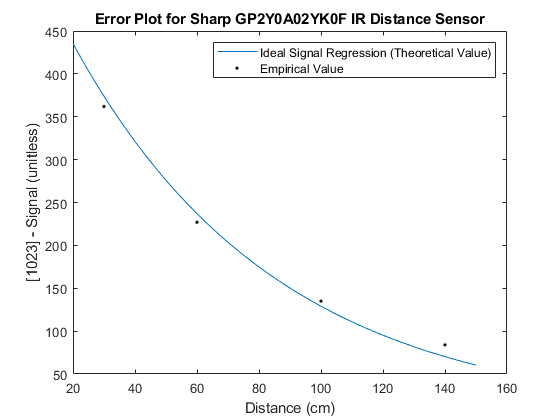

distance = linspace(20,150,130)';

signal = 590*exp(-0.0152.*distance);

plot(distance,signal);
hold on;
%%% OBTAINED VALUES %%%
plot(30,362,'k.');
plot(60,227,'k.');
plot(100,135,'k.');
plot(140,84,'k.');
%%%%%%%%%%%%%%%%%%%%%%%
title('Error Plot for Sharp GP2Y0A02YK0F IR Distance Sensor');
legend('Ideal Signal Regression (Theoretical Value)','Empirical Value')
xlabel('Distance (cm)');
ylabel('[1023] - Signal (unitless)');
hold off;

## Results with One Servo (Vertical)

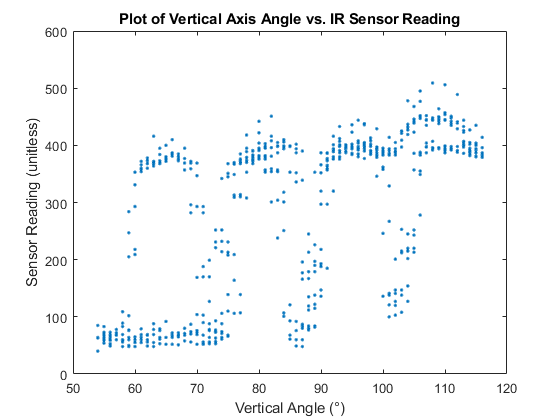

tiltScan = csvread('tiltdata.csv');

angle = tiltScan(:,1);
sensor1 = tiltScan(:,2);

plot(angle,sensor1,'.');
title('Plot of Vertical Axis Angle vs. IR Sensor Reading');
xlabel('Vertical Angle (°)');
ylabel('Sensor Reading (unitless)');

## Results with Two Servos (Horizontal & Veritcal)

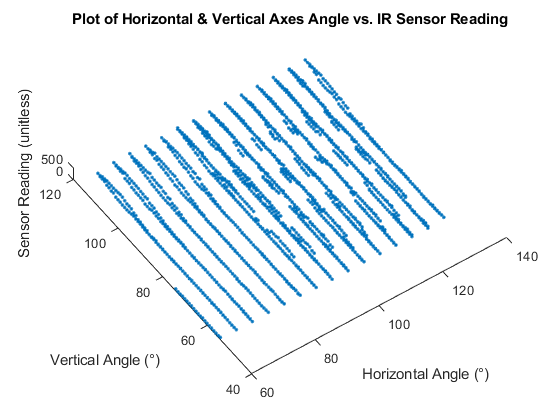

pantiltScan = csvread('pantiltdata.csv');

angle1 = pantiltScan(:,1);
angle2 = pantiltScan(:,2);
sensor2 = pantiltScan(:,3);

plot3(angle1,angle2,sensor2,'.');
title('Plot of Horizontal & Vertical Axes Angle vs. IR Sensor Reading');
xlabel('Horizontal Angle (°)');
ylabel('Vertical Angle (°)');
zlabel('Sensor Reading (unitless)');
view([-35 87])